# Basic Plotting

## Load data

load healthdata

## Histogram

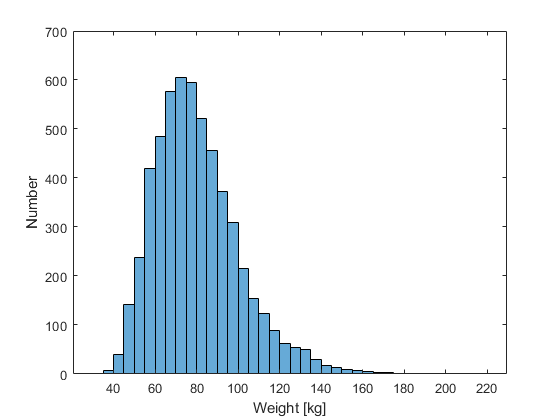

histogram(data.Weight)
xlabel('Weight [kg]')
ylabel('Number')

## Scatter plot

scatter(data.Height,data.Weight)

Or: 

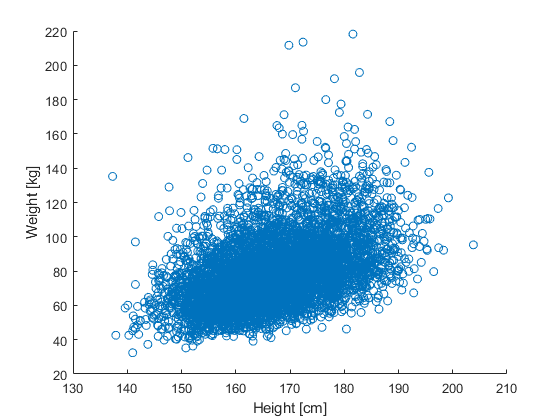


xlabel('Height [cm]')
ylabel('Weight [kg]')

## Scatter & histogram

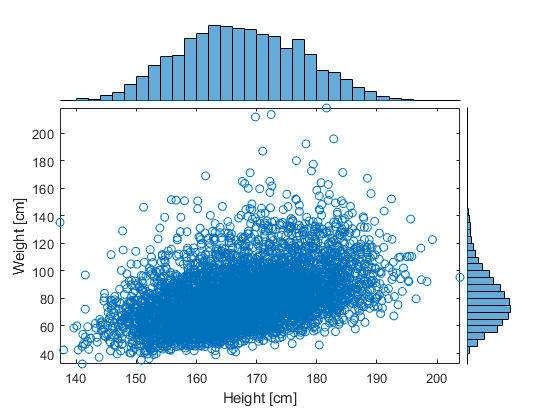

sh = scatterhistogram(data,'Height','Weight','HistogramDisplayStyle','bar',...
    'MarkerFilled','off');
sh.XLabel = 'Height [cm]';
sh.YLabel = 'Weight [cm]';

%Before R2018b:
% scatterhist(data.Height,data.Weight)
% xlabel('Height[cm]')
% ylabel('Weight [kg]')

## 3-D Scatter

scatter3(data.Height,data.Waist,data.Weight);

Or: 

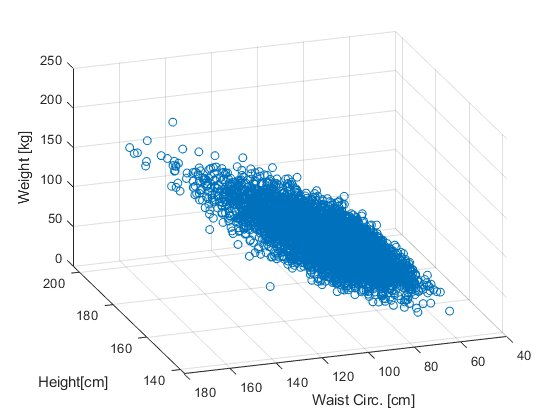


xlabel('Height[cm]')
ylabel('Waist Circ. [cm]')
zlabel('Weight [kg]')
view([-109 30])

## Look for correlations

Extract height, weight, and various measurements as a matrix

vars = {'Height', 'Weight', 'LegLength','ArmLength',...
    'ArmCirc','Waist', 'Triceps','Subscapular'}

vars = 1×8 cell array
  Columns 1 through 5
    {'Height'}    {'Weight'}    {'LegLength'}    {'ArmLength'}    {'ArmCirc'}
  Columns 6 through 8
    {'Waist'}    {'Triceps'}    {'Subscapular'}

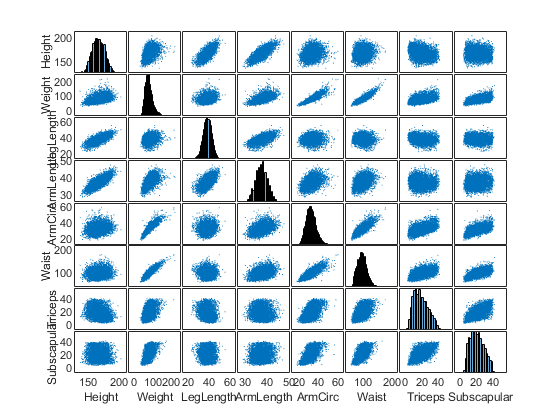

[~,ax] = plotmatrix(data{:,vars});

for k = 1:length(vars)
    ylabel(ax(k,1),vars(k))
    xlabel(ax(end,k),vars(k))
end